clc;
clear all;
close all;

## generate data

tfinal=500;
T_s=0.05

T_s = 0.0500

t = 0:T_s:tfinal;
u = zeros(numel(t),1);

#### General Input+white Noise

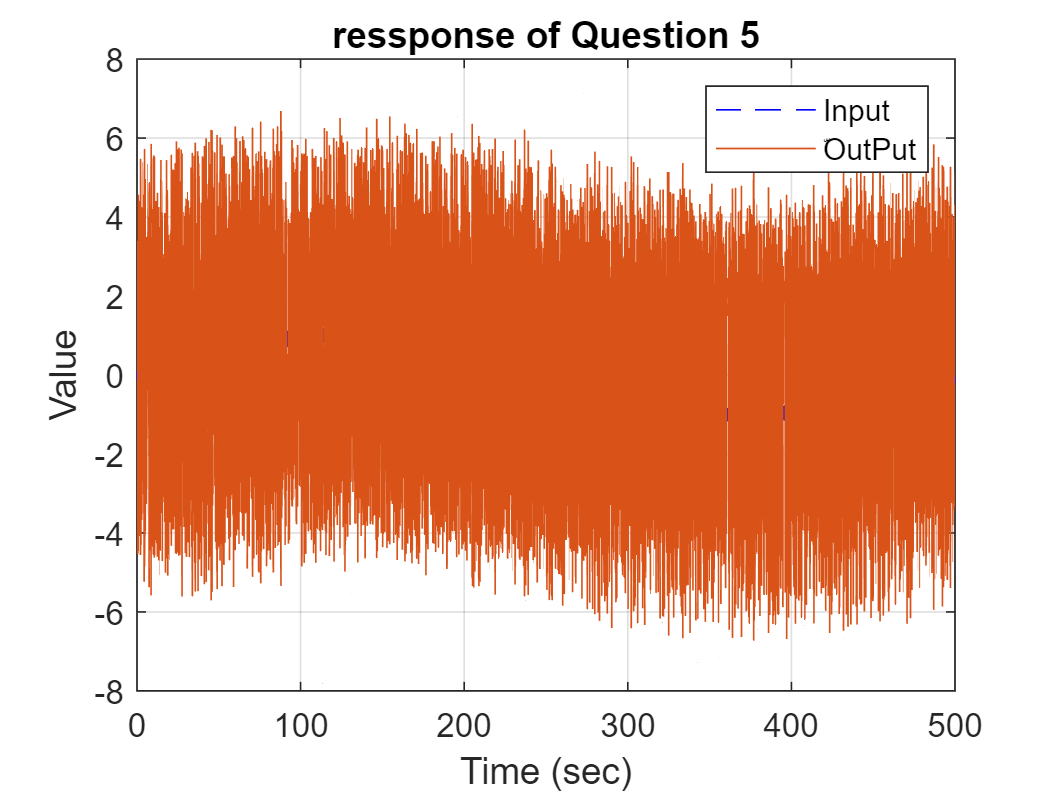

u = gensig('sine' , tfinal , tfinal ,T_s);
Noise=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise;

y(1:numel(t),1)=zeros(numel(t),1);
for i=3:numel(t)
    y(i)=-4*sin(2.2*y(i-2))+-0.34*y(i-1)+u(i);
end
plot(t,u,'b--',t , y ,'LineWidth',0.5) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 5') ;
grid on
legend('Input' , 'ّOutPut') ;

## Recursive Least Square estimation

N = numel(y) ;
%number of parameters
Parameters_in_den=100

Parameters_in_den = 100

Parameters_in_num=101

Parameters_in_num = 101

Nv=Parameters_in_num+Parameters_in_den

Nv = 201

phi=[];
Eror=zeros(1,N);
theta(1:Nv,1:Nv) = zeros(Nv,Nv) ;
P = 1e12*eye(Nv) ;
y_hat=[]


y_hat =

     []



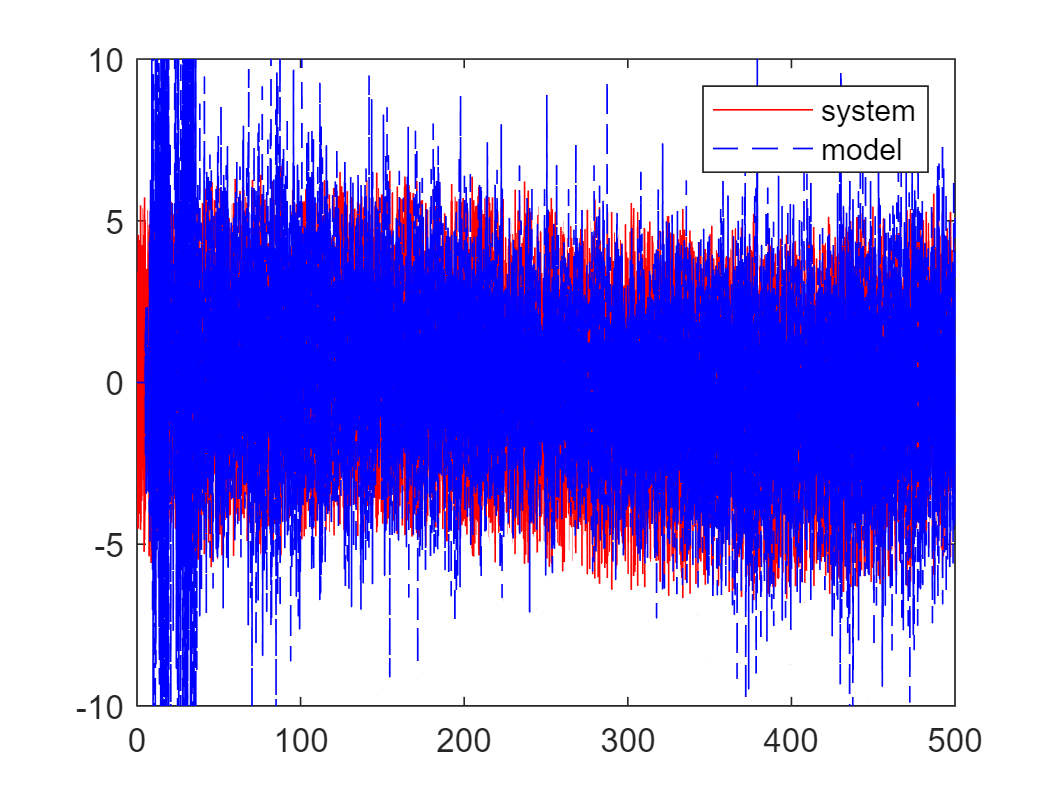

for i = (max(Parameters_in_num,Parameters_in_den)+1):N
   phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
   K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
   P = (eye(Nv) - K*phi(:,i)')*P ;
   y_hat(i)=phi(:,i)'*theta(:,i-1);
   theta(:,i) = theta(:,i-1) + K*(y(i) - y_hat(i)); 
end

plot(t,y,'r',t,y_hat,'b--')
legend('system','model')
ylim([-10 10])